# WPT-Solar Integration at 2 Ohms

## IV and PV Curves

filename = 'Integration_2.xlsx';
sheet = '2 Ohm';

% Read the data starting from the 3rd row (row 2 in Excel is header)
opts = detectImportOptions(filename, 'Sheet', sheet);
opts.DataRange = 'A3';
data = readtable(filename, opts);

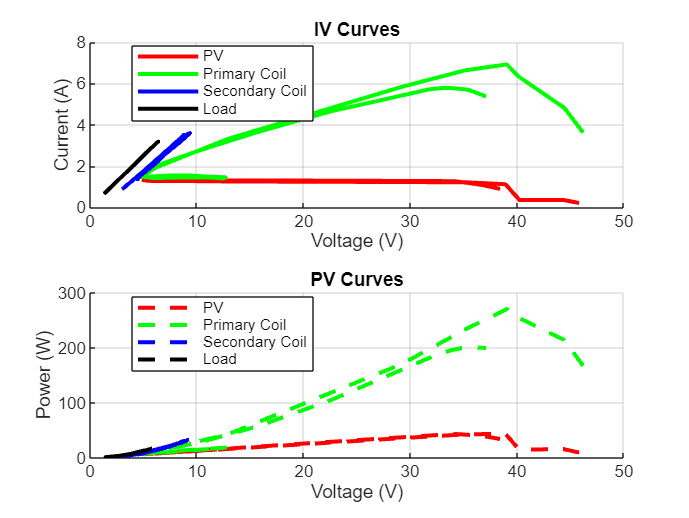


% Rename variables for clarity (optional, depending on actual headers)
V_PV = data.V_PV;
I_PV = data.I_PV;
P_PV = V_PV .* I_PV;

V_Prim = data.V_Primary;
I_Prim = data.I_Primary;
P_Prim = V_Prim .* I_Prim;

V_Sec = data.V_Secondary;
I_Sec = data.I_Secondary;
P_Sec = V_Sec .* I_Sec;

V_Load = data.V_Load;
I_Load = data.I_Load;
P_Load = V_Load .* I_Load;

% Plotting
figure;
tiledlayout(2,1);

% IV Curve
nexttile;
hold on;
plot(V_PV, I_PV, 'r', 'LineWidth', 2, 'DisplayName', 'PV');
plot(V_Prim, I_Prim, 'g', 'LineWidth', 2, 'DisplayName', 'Primary Coil');
plot(V_Sec, I_Sec, 'b', 'LineWidth', 2, 'DisplayName', 'Secondary Coil');
plot(V_Load, I_Load, 'k', 'LineWidth', 2, 'DisplayName', 'Load');
xlabel('Voltage (V)');
ylabel('Current (A)');
title('IV Curves');
legend('Location','best');
grid on;

% PV Curve
nexttile;
hold on;
plot(V_PV, P_PV, 'r--', 'LineWidth', 2, 'DisplayName', 'PV');
plot(V_Prim, P_Prim, 'g--', 'LineWidth', 2, 'DisplayName', 'Primary Coil');
plot(V_Sec, P_Sec, 'b--', 'LineWidth', 2, 'DisplayName', 'Secondary Coil');
plot(V_Load, P_Load, 'k--', 'LineWidth', 2, 'DisplayName', 'Load');
xlabel('Voltage (V)');
ylabel('Power (W)');
title('PV Curves');
legend('Location','best');
grid on;

## Power vs Frequency

% Load the data
filename = 'Integration_2.xlsx';
data = readtable(filename);

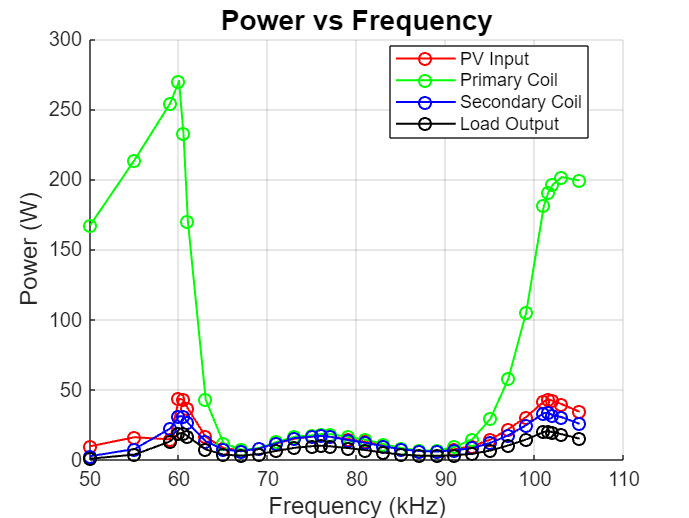


% Get unique frequencies
frequencies = unique(data.Frequency);

% Preallocate max power arrays
maxP_PV = zeros(length(frequencies),1);
maxP_Prim = zeros(length(frequencies),1);
maxP_Sec = zeros(length(frequencies),1);
maxP_Load = zeros(length(frequencies),1);

% Loop through each frequency block
for i = 1:length(frequencies)
    freq = frequencies(i);
    idx = data.Frequency == freq;

    % PV Stage
    V_PV = data.V_PV(idx);
    I_PV = data.I_PV(idx);
    P_PV = V_PV .* I_PV;
    maxP_PV(i) = max(P_PV);

    % Primary Coil
    V_Prim = data.V_Primary(idx);
    I_Prim = data.I_Primary(idx);
    P_Prim = V_Prim .* I_Prim;
    maxP_Prim(i) = max(P_Prim);

    % Secondary Coil
    V_Sec = data.V_Secondary(idx);
    I_Sec = data.I_Secondary(idx);
    P_Sec = V_Sec .* I_Sec;
    maxP_Sec(i) = max(P_Sec);

    % Load
    V_Load = data.V_Load(idx);
    I_Load = data.I_Load(idx);
    P_Load = V_Load .* I_Load;
    maxP_Load(i) = max(P_Load);
end

% Plot
figure;
hold on;
plot(frequencies, maxP_PV, 'r-o', 'LineWidth', 1, 'DisplayName', 'PV Input');
plot(frequencies, maxP_Prim, 'g-o', 'LineWidth', 1, 'DisplayName', 'Primary Coil');
plot(frequencies, maxP_Sec, 'b-o', 'LineWidth', 1, 'DisplayName', 'Secondary Coil');
plot(frequencies, maxP_Load, 'k-o', 'LineWidth', 1, 'DisplayName', 'Load Output');

xlabel('Frequency (kHz)', 'FontSize', 12);
ylabel('Power (W)', 'FontSize', 12);
title('Power vs Frequency', 'FontSize', 14);
legend('Location','best');
grid on;

## Load Power vs Frequency

% Load the data
filename = 'Integration_2.xlsx';
data = readtable(filename);

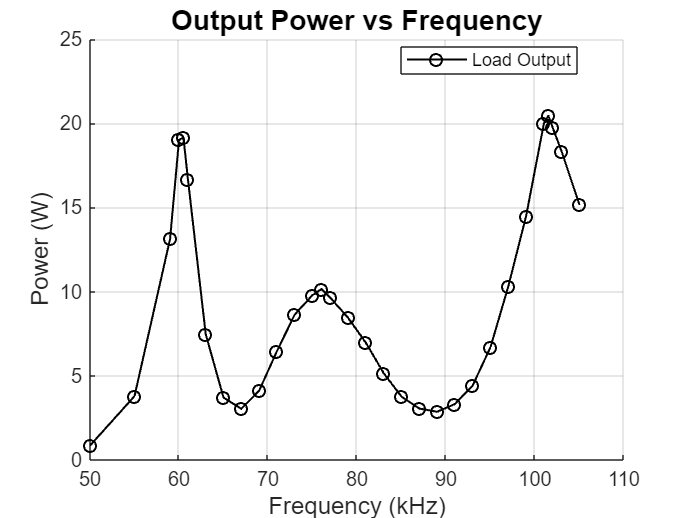


% Get unique frequencies
frequencies = unique(data.Frequency);

% Preallocate max power arrays
maxP_Load = zeros(length(frequencies),1);

% Loop through each frequency block
for i = 1:length(frequencies)
    freq = frequencies(i);
    idx = data.Frequency == freq;

    % Load
    V_Load = data.V_Load(idx);
    I_Load = data.I_Load(idx);
    P_Load = V_Load .* I_Load;
    maxP_Load(i) = max(P_Load);
end

% Plot
figure;
hold on;
plot(frequencies, maxP_Load, 'k-o', 'LineWidth', 1, 'DisplayName', 'Load Output');

xlabel('Frequency (kHz)', 'FontSize', 12);
ylabel('Power (W)', 'FontSize', 12);
title('Output Power vs Frequency', 'FontSize', 14);
legend('Location','best');
grid on;

## Overall Efficiency vs Frequency

% Load the data
filename = 'Integration_2.xlsx';
data = readtable(filename);

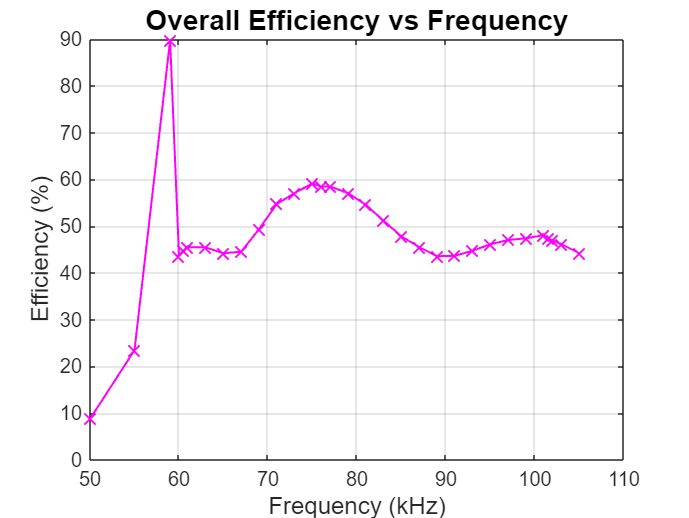


% Get unique frequencies
frequencies = unique(data.Frequency);

% Preallocate arrays
maxP_PV = zeros(length(frequencies),1);
maxP_Load = zeros(length(frequencies),1);
efficiency = zeros(length(frequencies),1);

% Loop through each frequency block
for i = 1:length(frequencies)
    freq = frequencies(i);
    idx = data.Frequency == freq;

    % PV Input
    V_PV = data.V_PV(idx);
    I_PV = data.I_PV(idx);
    P_PV = V_PV .* I_PV;
    maxP_PV(i) = max(P_PV);

    % Load Output
    V_Load = data.V_Load(idx);
    I_Load = data.I_Load(idx);
    P_Load = V_Load .* I_Load;
    maxP_Load(i) = max(P_Load);

    % Efficiency
    if maxP_PV(i) > 0
        efficiency(i) = (maxP_Load(i) / maxP_PV(i)) * 100;
    else
        efficiency(i) = 0;
    end
end

% Plot efficiency vs frequency
figure;
plot(frequencies, efficiency, 'm-x', 'LineWidth', 1, 'MarkerSize', 8);
xlabel('Frequency (kHz)', 'FontSize', 12);
ylabel('Efficiency (%)', 'FontSize', 12);
title('Overall Efficiency vs Frequency', 'FontSize', 14);
grid on;

## Voltage/Current vs Frequency

% Loads the data
filename = 'Integration_2.xlsx';
data = readtable(filename);

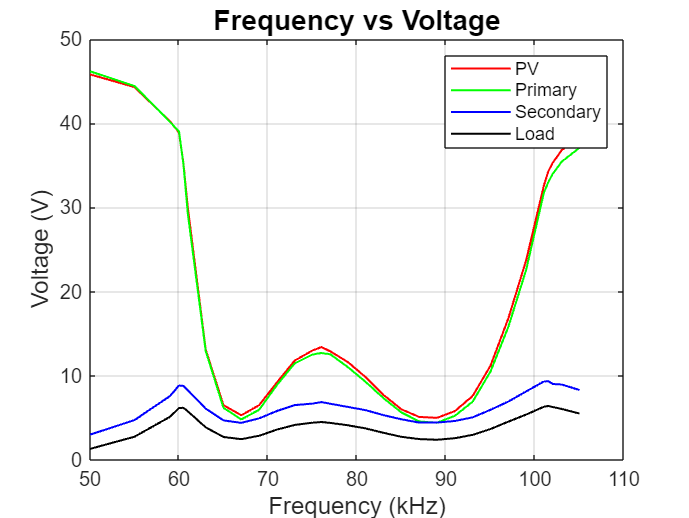


% Gets unique frequencies
frequencies = unique(data.Frequency);

% Preallocates arrays
maxV_PV = zeros(length(frequencies),1);
maxV_Primary = zeros(length(frequencies),1);
maxV_Secondary = zeros(length(frequencies),1);
maxV_Load = zeros(length(frequencies),1);

maxI_PV = zeros(length(frequencies),1);
maxI_Primary = zeros(length(frequencies),1);
maxI_Secondary = zeros(length(frequencies),1);
maxI_Load = zeros(length(frequencies),1);

% Loops through each frequency block
for i = 1:length(frequencies)
    freq = frequencies(i);
    idx = data.Frequency == freq;

    % Voltage
    maxV_PV(i) = max(data.V_PV(idx));
    maxV_Primary(i) = max(data.V_Primary(idx));
    maxV_Secondary(i) = max(data.V_Secondary(idx));
    maxV_Load(i) = max(data.V_Load(idx));

    % Current
    maxI_PV(i) = max(data.I_PV(idx));
    maxI_Primary(i) = max(data.I_Primary(idx));
    maxI_Secondary(i) = max(data.I_Secondary(idx));
    maxI_Load(i) = max(data.I_Load(idx));
end

% Plots Frequency vs Voltage
figure;
plot(frequencies, maxV_PV, 'r-', 'LineWidth', 1); hold on;
plot(frequencies, maxV_Primary, 'g-', 'LineWidth', 1);
plot(frequencies, maxV_Secondary, 'b-', 'LineWidth', 1);
plot(frequencies, maxV_Load, 'k-', 'LineWidth', 1);
xlabel('Frequency (kHz)', 'FontSize', 12);
ylabel('Voltage (V)', 'FontSize', 12);
title('Frequency vs Voltage', 'FontSize', 14);
legend('PV', 'Primary', 'Secondary', 'Load');
grid on;

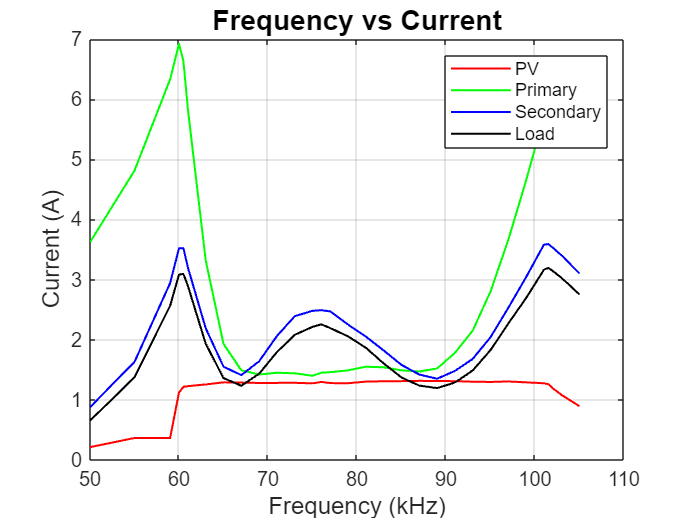


% Plots Frequency vs Current
figure;
plot(frequencies, maxI_PV, 'r-', 'LineWidth', 1); hold on;
plot(frequencies, maxI_Primary, 'g-', 'LineWidth', 1);
plot(frequencies, maxI_Secondary, 'b-', 'LineWidth', 1);
plot(frequencies, maxI_Load, 'k-', 'LineWidth', 1);
xlabel('Frequency (kHz)', 'FontSize', 12);
ylabel('Current (A)', 'FontSize', 12);
title('Frequency vs Current', 'FontSize', 14);
legend('PV', 'Primary', 'Secondary', 'Load');
grid on;

## Stage Efficiencies vs Frequency

% Loads the data
filename = 'Integration_2.xlsx';
data = readtable(filename);

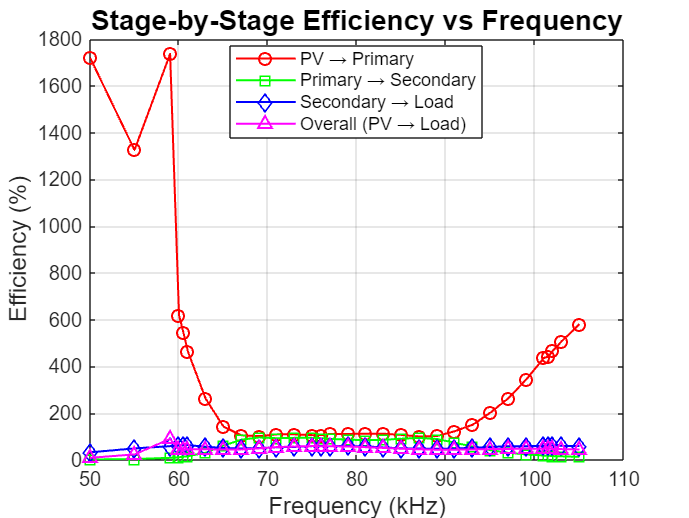


% Gets unique frequencies
frequencies = unique(data.Frequency);

% Preallocate arrays
maxP_PV = zeros(length(frequencies),1);
maxP_Primary = zeros(length(frequencies),1);
maxP_Secondary = zeros(length(frequencies),1);
maxP_Load = zeros(length(frequencies),1);

eff1 = zeros(length(frequencies),1);  % PV → Primary
eff2 = zeros(length(frequencies),1);  % Primary → Secondary
eff3 = zeros(length(frequencies),1);  % Secondary → Load
eff_total = zeros(length(frequencies),1);  % PV → Load

% Loops through each frequency block
for i = 1:length(frequencies)
    freq = frequencies(i);
    idx = data.Frequency == freq;

    % Computes power at each stage
    P_PV = data.V_PV(idx) .* data.I_PV(idx);
    P_Primary = data.V_Primary(idx) .* data.I_Primary(idx);
    P_Secondary = data.V_Secondary(idx) .* data.I_Secondary(idx);
    P_Load = data.V_Load(idx) .* data.I_Load(idx);

    maxP_PV(i) = max(P_PV);
    maxP_Primary(i) = max(P_Primary);
    maxP_Secondary(i) = max(P_Secondary);
    maxP_Load(i) = max(P_Load);

    % Efficiency calculations (avoid division by zero)
    if maxP_PV(i) > 0
        eff1(i) = (maxP_Primary(i) / maxP_PV(i)) * 100;
        eff_total(i) = (maxP_Load(i) / maxP_PV(i)) * 100;
    else
        eff1(i) = 0;
        eff_total(i) = 0;
    end

    if maxP_Primary(i) > 0
        eff2(i) = (maxP_Secondary(i) / maxP_Primary(i)) * 100;
    else
        eff2(i) = 0;
    end

    if maxP_Secondary(i) > 0
        eff3(i) = (maxP_Load(i) / maxP_Secondary(i)) * 100;
    else
        eff3(i) = 0;
    end

end

% Plots efficiencies
figure;
plot(frequencies, eff1, 'r-o', 'LineWidth', 1); hold on;
plot(frequencies, eff2, 'g-s', 'LineWidth', 1);
plot(frequencies, eff3, 'b-d', 'LineWidth', 1);
plot(frequencies, eff_total, 'm-^', 'LineWidth', 1);
xlabel('Frequency (kHz)', 'FontSize', 12);
ylabel('Efficiency (%)', 'FontSize', 12);
title('Stage-by-Stage Efficiency vs Frequency', 'FontSize', 14);
legend('PV → Primary', 'Primary → Secondary', 'Secondary → Load', 'Overall (PV → Load)', 'Location', 'best');
grid on;



% Creates a table of efficiencies
effTable = table(frequencies, eff1, eff2, eff3, eff_total, ...
    'VariableNames', {'Frequency_kHz', 'PV_to_Primary_%', 'Primary_to_Secondary_%', ...
                      'Secondary_to_Load_%', 'Overall_PV_to_Load_%'});

% Displays the table in the Command Window
disp(effTable);

    Frequency_kHz    PV_to_Primary_%    Primary_to_Secondary_%    Secondary_to_Load_%    Overall_PV_to_Load_%
    _____________    _______________    ______________________    ___________________    ____________________

           50            1721.3                 1.5724                  32.362                   8.759       
           55            1325.6                  3.607                   49.08                  23.466       
           59            1736.4                 8.7939                  58.778                  89.753       
           60            619.31                 11.521                  61.086                  43.585       
         60.5            544.13                 13.296                  61.872                  44.762       
           61            463.62                 15.505     

## Plot without PV --> Primary

% Load the data
filename = 'Integration_2.xlsx';
data = readtable(filename);

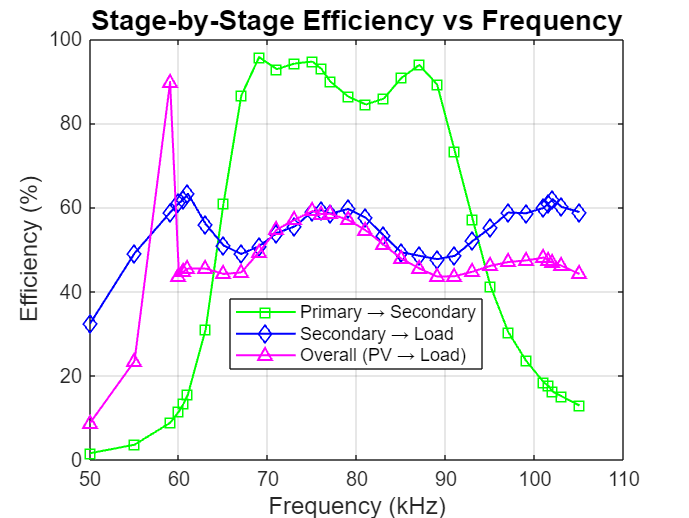


% Get unique frequencies
frequencies = unique(data.Frequency);

% Preallocate arrays
maxP_PV = zeros(length(frequencies),1);
maxP_Primary = zeros(length(frequencies),1);
maxP_Secondary = zeros(length(frequencies),1);
maxP_Load = zeros(length(frequencies),1);

eff1 = zeros(length(frequencies),1);  % PV → Primary
eff2 = zeros(length(frequencies),1);  % Primary → Secondary
eff3 = zeros(length(frequencies),1);  % Secondary → Load
eff_total = zeros(length(frequencies),1);  % PV → Load

% Loop through each frequency block
for i = 1:length(frequencies)
    freq = frequencies(i);
    idx = data.Frequency == freq;

    % Compute power at each stage
    P_PV = data.V_PV(idx) .* data.I_PV(idx);
    P_Primary = data.V_Primary(idx) .* data.I_Primary(idx);
    P_Secondary = data.V_Secondary(idx) .* data.I_Secondary(idx);
    P_Load = data.V_Load(idx) .* data.I_Load(idx);

    maxP_PV(i) = max(P_PV);
    maxP_Primary(i) = max(P_Primary);
    maxP_Secondary(i) = max(P_Secondary);
    maxP_Load(i) = max(P_Load);

    % Efficiency calculations (avoid division by zero)
    if maxP_PV(i) > 0
        eff1(i) = (maxP_Primary(i) / maxP_PV(i)) * 100;
        eff_total(i) = (maxP_Load(i) / maxP_PV(i)) * 100;
    else
        eff1(i) = 0;
        eff_total(i) = 0;
    end

    if maxP_Primary(i) > 0
        eff2(i) = (maxP_Secondary(i) / maxP_Primary(i)) * 100;
    else
        eff2(i) = 0;
    end

    if maxP_Secondary(i) > 0
        eff3(i) = (maxP_Load(i) / maxP_Secondary(i)) * 100;
    else
        eff3(i) = 0;
    end

end

% Plot efficiencies
figure;
plot(frequencies, eff2, 'g-s', 'LineWidth', 1); hold on;
plot(frequencies, eff3, 'b-d', 'LineWidth', 1);
plot(frequencies, eff_total, 'm-^', 'LineWidth', 1);
xlabel('Frequency (kHz)', 'FontSize', 12);
ylabel('Efficiency (%)', 'FontSize', 12);
title('Stage-by-Stage Efficiency vs Frequency', 'FontSize', 14);
legend('Primary → Secondary', 'Secondary → Load', 'Overall (PV → Load)', 'Location', 'best');
grid on;